In this notebook, for each arm design we will sweep thorugh a variety of pressure and loading configurations in order to plot how each arm's workspace under load. Here, we define "workspace" to mean the arc of furthest reaching. Thus, for the two muscle arm, we will sweep through actuator 1 being pressurized, and then actuator 2 being pressurized. For the antagonist am, this will be when an antagonistic pair works together.

%% Global variables
% Define baseline arm geometry
rho_outer_base = 0.06;
rho_inner_base = 0.015;
rho_outer_tip = 0.02;
rho_inner_tip = 0.015;
l_0 = 0.5;
N_seg = 6;

% Generate workspace plot for a single arm design
straight_wide_muscle_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_seg, rho_outer_base, l_0);
straight_wide_muscle_arm.set_mechanics(GinaMuscleMechanics(l_0));

ax = axes(figure("Position", [0, 0, 500, 800]));
straight_wide_tip_poses = plot_loaded_workspace_mesh(straight_wide_muscle_arm, ax, 4, 10, 10, [0; 1]);

Elapsed time is 68.512143 seconds.


straight_narrow_muscle_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_seg, rho_inner_base, l_0);
straight_narrow_muscle_arm.set_mechanics(GinaMuscleMechanics(l_0));

ax = axes(figure("Position", [0, 0, 500, 800]));
plot_loaded_workspace_mesh(straight_narrow_muscle_arm, ax, 4, 10, 10, [0; 1]);

fzero residual is nonzero (> 0.01). Printing: 
   -0.0001   -0.0001   -0.0004    0.0004    0.0020    0.0010
   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0093   -0.0099   -0.0437    0.0305    0.1205    0.0727
fzero residual is nonzero (> 0.01). Printing: 
    0.0003   -0.0000    0.0006    0.0011    0.0000   -0.0001
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0188   -0.0319    0.0461   -0.0024   -0.0057   -0.0067
fzero residual is nonzero (> 0.01). Printing: 
   -0.0001   -0.0000    0.0001   -0.0000   -0.0001    0.0003
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0040   -0.0018    0.0080   -0.0029   -0.0054    0.0244
fzero residual is nonzero (> 0.01). Printing: 
    0.0018    0.0018   -0.0010   -0.0000    0.0022   -0.0002
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1243    0.1292    0.0028   -0.0116    0.0133    0.0059
fzero residual is nonzero (> 0.01). Printing: 
    0.0000    0.0000    0.0010   

% Generate workspace plot for a single arm design
straight_medium_muscle_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_seg, 0.02, l_0);
straight_medium_muscle_arm.set_mechanics(GinaMuscleMechanics(l_0));

ax = axes(figure("Position", [0, 0, 500, 800]));
plot_loaded_workspace_mesh(straight_medium_muscle_arm, ax, 4, 10, 10, [0; 1]);

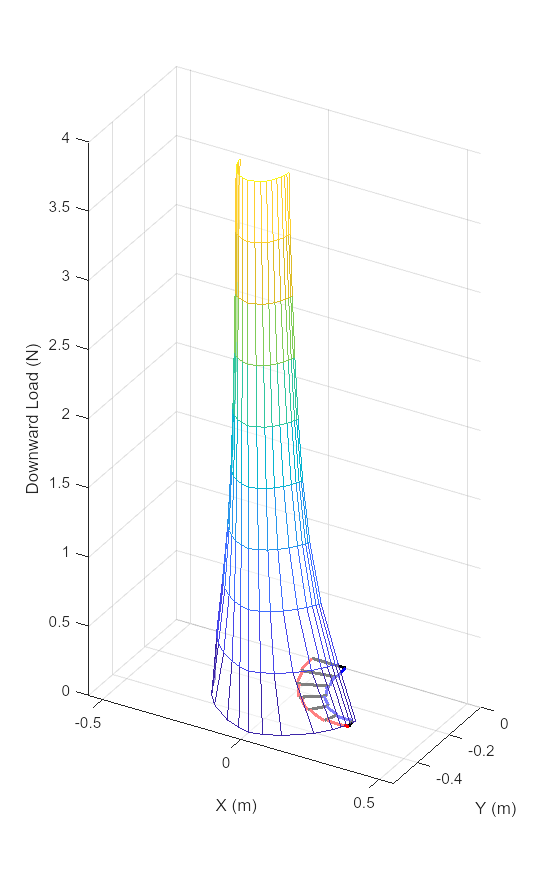

fzero residual is nonzero (> 0.01). Printing: 
   -0.0000   -0.0001   -0.0002    0.0000    0.0003    0.0003
   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0005   -0.0015   -0.0044    0.0004    0.0100    0.0202
fzero residual is nonzero (> 0.01). Printing: 
   -0.0000    0.0000   -0.0001   -0.0001   -0.0001    0.0007
   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0010   -0.0027   -0.0018   -0.0059    0.0354
Elapsed time is 141.332603 seconds.


% Loaded workspace of tapered arm
tapered_muscle_arm = ArmSeriesFactory.tapered_2d_muscle_arm(N_seg, rho_outer_base, rho_outer_tip, l_0);
tapered_muscle_arm.set_mechanics(GinaMuscleMechanics(l_0));

ax = axes(figure("Position", [0, 0, 500, 800]));
tapered_tip_poses = plot_loaded_workspace_mesh(tapered_muscle_arm, ax, 4, 10, 10, [0; 1]);

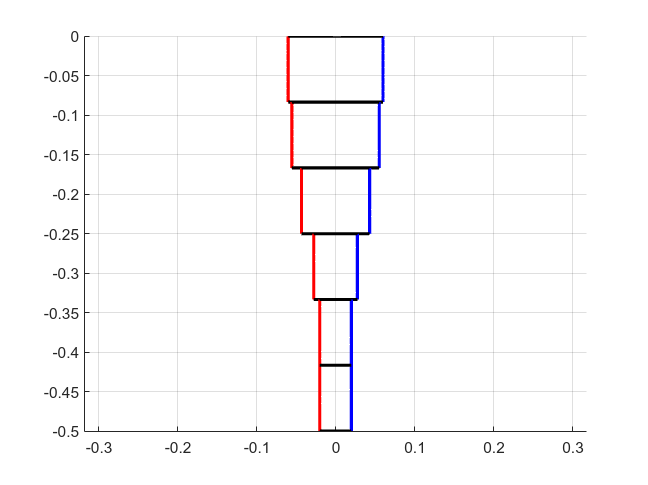

varying_taper_arm = ArmSeriesFactory.constant_force_taper_2d_muscle_arm(N_seg, 0.06, 0.02, l_0);
varying_taper_arm.set_mechanics(GinaMuscleMechanics(l_0));

Plotter2D.plot_arm_series(varying_taper_arm, axes(figure()))

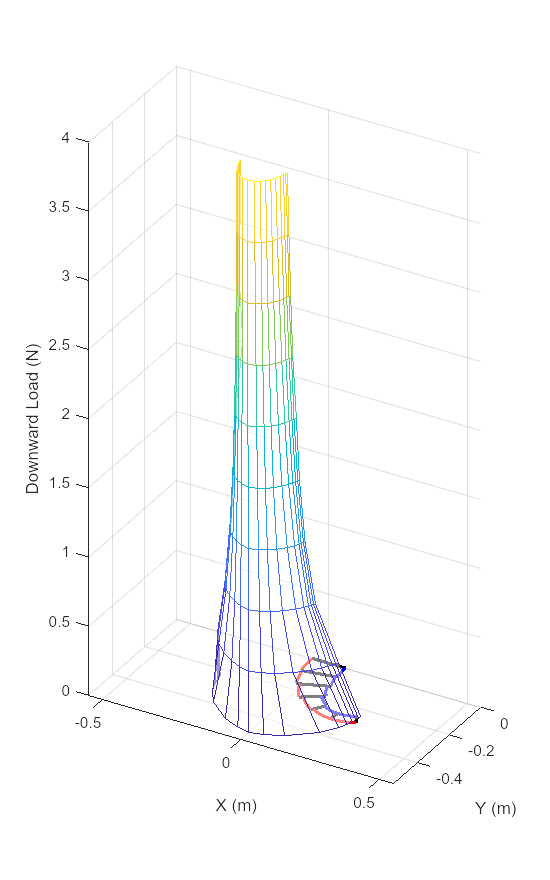

fzero residual is nonzero (> 0.01). Printing: 
    0.0000    0.0000    0.0000   -0.0004    0.0002    0.0008
    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0008    0.0009    0.0014   -0.0167    0.0122    0.0458
fzero residual is nonzero (> 0.01). Printing: 
   -0.0000   -0.0000   -0.0000   -0.0000    0.0002   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0002   -0.0005   -0.0004   -0.0014    0.0109   -0.0013
fzero residual is nonzero (> 0.01). Printing: 
    0.0000    0.0000    0.0000   -0.0004    0.0002   -0.0000
    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0002    0.0003    0.0006   -0.0141    0.0144   -0.0016
fzero residual is nonzero (> 0.01). Printing: 
    0.0000   -0.0000   -0.0000   -0.0000    0.0002   -0.0001
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0002   -0.0003   -0.0016    0.0129   -0.0051
fzero residual is nonzero (> 0.01). Printing: 
    0.0000    0.0001   -0.0001   

ax = axes(figure("Position", [0, 0, 500, 800]));
varying_taper_tip_poses = plot_loaded_workspace_mesh(varying_taper_arm, ax, 4, 10, 10, [0; 1]);

figure()
straight_poses_max_load = [straight_wide_tip_poses{end, :}];
narrow_poses_max_load = [];

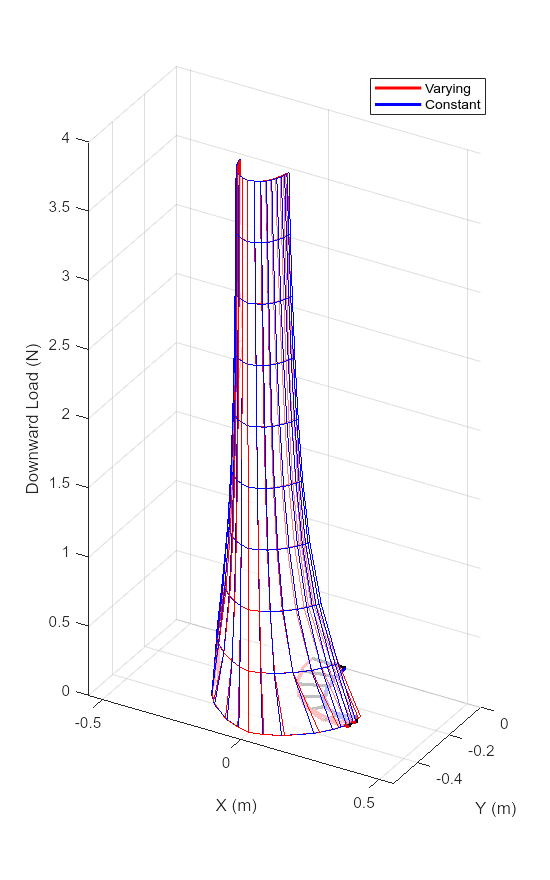

ax = axes(figure("Position", [0, 0, 500, 800]));
plot_tip_poses(tapered_muscle_arm, tapered_tip_poses, linspace(0, 100, 10), linspace(0, 4, 10), [0; 1], ax, 'blue');
plot_tip_poses(varying_taper_arm, varying_taper_tip_poses, linspace(0, 100, 10), linspace(0, 4, 10), [0; 1], ax, 'red');
legend(["Varying", "Constant"], "location", "northeast")

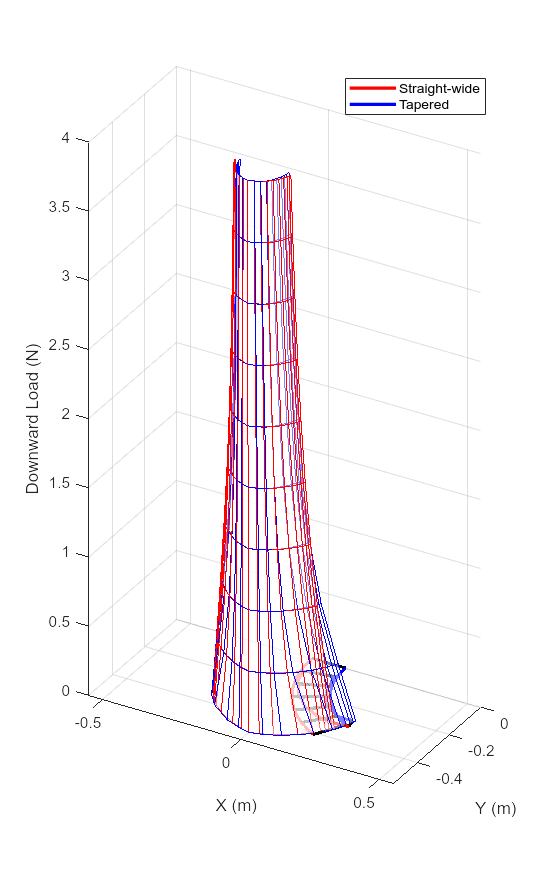

ax = axes(figure("Position", [0, 0, 500, 800]));
plot_tip_poses(tapered_muscle_arm, tapered_tip_poses, linspace(0, 100, 10), linspace(0, 4, 10), [0; 1], ax, 'blue');
plot_tip_poses(straight_wide_muscle_arm, straight_wide_tip_poses, linspace(0, 100, 10), linspace(0, 4, 10), [0; 1], ax, 'red');
legend(["Straight-wide", "Tapered"], "location", "northeast")

function cell_tip_poses = plot_loaded_workspace_mesh(arm_series, ax, max_load, N_p, N_loads, p_basis)
    arguments
        arm_series
        ax
        max_load
        N_p = 10;
        N_loads = 10;
        p_basis = [0; 1];
    end
    %% Solve for arm tip poses across our range of pressures and loads
    % Create the space of pressures and loads to sweep through
    max_p = 100;
    loads = linspace(0, max_load, N_loads);
    pressures = linspace(0, max_p, N_p);
    
    cell_g_circ_right = cell(N_loads, N_p);
    cell_tip_poses = cell(N_loads, N_p);
    tic;
    for i = 1 : length(loads)
        Q_i = [0; -loads(i); 0];
        for j = 1 : length(pressures)
            p_j = pressures(j) * p_basis;
            cell_g_circ_right{i, j} = arm_series.solve_equilibrium_gina(p_j, Q_i, "frame", "World");
            cell_tip_poses{i, j} = Pose2.vee(arm_series.get_tip_pose());
        end
    end
    toc

    %% Create the mesh in XYZ space
    % TODO: The following plotting code is redundant with the function
    % below
    X = zeros(N_loads, N_p);
    Y = zeros(N_loads, N_p);
    Z = zeros(N_loads, N_p);
    for i = 1 : N_loads
        load_i = loads(i);
        for j = 1 : N_p
            tip_pose_ij = cell_tip_poses{i, j};
            X(i, j) = tip_pose_ij(1);
            Y(i, j) = tip_pose_ij(2);
            Z(i, j) = load_i;
        end
    end

    %% Solve an example arm and plot it
    p_example = max_p * 0.8 * p_basis;
    arm_series.solve_equilibrium_gina(p_example, [0; 0; 0]);
    Plotter2D.plot_arm_series(arm_series, ax);
    
    %% Plotting
    hold(ax, "on");
    mesh(ax, X, Y, Z, "facealpha", 0.5)
    mesh(ax, -X, Y, Z, "facealpha", 0.5)

    grid(ax, "on")
    view(ax, 30, 30)
    daspect([1, 1, 2]);
    ylim(ax, [-0.55, 0])
    xlim(ax, [-0.55, 0.55]);

    xlabel("X (m)")
    ylabel("Y (m)")
    zlabel("Downward Load (N)")
end

function plot_tip_poses(arm_series, cell_tip_poses, pressures, loads, p_basis, ax, color)
    [N_loads, N_p] = size(cell_tip_poses);

    %% Create the mesh in XYZ space
    X = zeros(N_loads, N_p);
    Y = zeros(N_loads, N_p);
    Z = zeros(N_loads, N_p);
    for i = 1 : N_loads
        load_i = loads(i);
        for j = 1 : N_p
            tip_pose_ij = cell_tip_poses{i, j};
            X(i, j) = tip_pose_ij(1);
            Y(i, j) = tip_pose_ij(2);
            Z(i, j) = load_i;
        end
    end

    %% Solve an example arm and plot it
    max_p = max(pressures);
    p_example = max_p * 0.8 * p_basis;
    arm_series.solve_equilibrium_gina(p_example, [0; 0; 0]);
    Plotter2D.plot_arm_series(arm_series, ax);
    
    %% Plotting
    hold(ax, "on");
    mesh(ax, X, Y, Z, "facealpha", 0.5, 'edgecolor', color)
    mesh(ax, -X, Y, Z, "facealpha", 0.5, 'edgecolor', color)

    grid(ax, "on")
    view(ax, 30, 30)
    daspect([1, 1, 2]);
    ylim(ax, [-0.55, 0])
    xlim(ax, [-0.55, 0.55]);

    xlabel("X (m)")
    ylabel("Y (m)")
    zlabel("Downward Load (N)")
end